# Q1Q2 Investigation

Show combination of Q1 and Q2 on a strip length. Strip width of 1.4 m.

We can solve for alphaQ2 given what we know about Q1 from Q1Investigation (alphaQ1 = 0.6).

Produced using Q1Q2MaxEventsx, which comes from VBWIMQ1Q2.

*Can also use Q1Q2MaxEvents which comes from MATSimAxles in SwissTraffic - not as good*

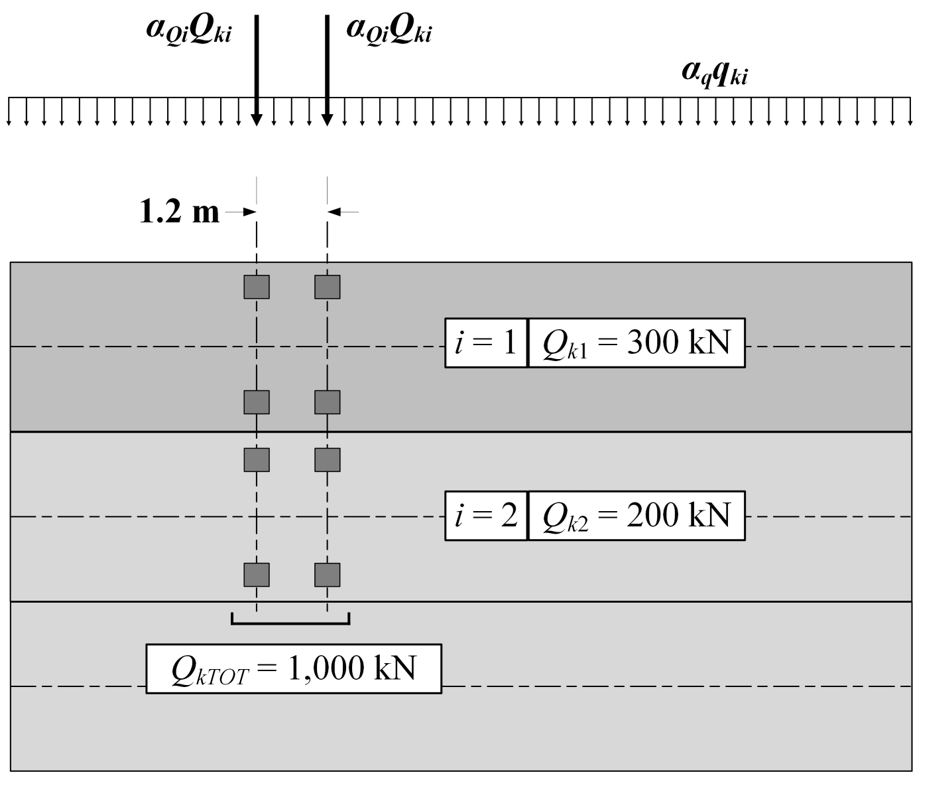

To save time, user can choose to skip the first 4 steps by loading Q1Q2MaxEventsxMax, Q1Q2MaxEventsxpd, and Q1Q2MaxEventsxy_values.

In this case, the default Input values in Step 1 are used. Only available for Q1Q2MaxEventsx (not Q1Q2MaxEvents).

Questions being answered:

- What distribution works best for the block maxima? Steps 4, 5

- How well does it work? Step 6

- What is the updated alpha coefficient? Step 7

- Characteristics of vehicles involved

- Axle ratios, spacing (Q1 only)

- Speed, Times, Class

% Initial commands
clear, clc, close all
% This function loads the variable 'Q1Q2MaxEvents' which is produced by 'MATSimAxles'
load('Q1Q2MaxEventsx.mat')

### Step 1: Input desired filters/parameters

% Select which year to analyze %Years = 2011:2019;
Years = 0;
% Select stations (locations) to analyze %Stations = [408 409 405 406 402 415 416];
Stations = 0;

% Block Maxima (always use j)
BM = {'Daily', 'Weekly', 'Yearly'};

% Select which Classification you want to analyze (always use i)
ClassType = {'All', 'ClassOW', 'Class'};
% Must be in the order 'All' 'ClassOW' 'Class' due to deletions
ClassT = {'All', 'Classified+', 'Classified'};

### Step 2: Filter Axles based on desired year and station (location)

% Filter Axles based on desired year and station (location)
if Stations > 0
    y = MaxEvents.SITE == Stations;
    MaxEvents(~any(y,2),:) = [];
end
if Years > 0
    y = year(MaxEvents.DTS) == Years;
    MaxEvents(~any(y,2),:) = [];
end

### Step 3: Build Structure with Block Maxima

% Convert ClassT to m (number) form m = 1 is All, m = 2 is ClassOW, m = 3 is Class
MaxEvents.m(strcmp(MaxEvents.ClassT,"All")) = 1;
MaxEvents.m(strcmp(MaxEvents.ClassT,"ClassOW")) = 2;
MaxEvents.m(strcmp(MaxEvents.ClassT,"Class")) = 3; MaxEvents.ClassT = [];

% Transform AxTandem into Array (necessary for splitapply)
Z = MaxEvents;
% Convert Datetime to Datenum for the sake of array
Z.DTS = datenum(Z.DTS); Z = table2array(Z);
            
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    % Filter based on Class - MaxEvents is compromised after this (deleting entries)
    if strcmp(Class,'ClassOW')
        MaxEvents(MaxEvents.m == 1,:) = []; %#ok<*SAGROW> 
        Z(Z(:,end) == 1,:) = [];
    elseif strcmp(Class,'Class')
        MaxEvents(MaxEvents.m == 1,:) = [];
        Z(Z(:,end) == 1,:) = [];
        MaxEvents(MaxEvents.m == 2,:) = [];
        Z(Z(:,end) == 2,:) = [];
    end
      
    for j = 1:length(BM)
        BlockM = BM{j};
        
        % Initialize
        Max.(Class).(BlockM) = [];
        
        if strcmp(BlockM,'Daily')
            
            % Make groups out of unique locations and days
            [Gr, GrIDDay, GrIDSITE] = findgroups(dateshift(MaxEvents.DTS,'start','day'),MaxEvents.SITE);
            
        elseif strcmp(BlockM,'Weekly')
            [Gr, GrIDWeek, GrIDSITE] = findgroups(dateshift(MaxEvents.DTS,'start','week'),MaxEvents.SITE);
        else          
            [Gr, GrIDYear, GrIDSITE] = findgroups(year(MaxEvents.DTS),MaxEvents.SITE);
        end
        
        % Perform splitapply (see function at end... not just Max as we want whole rows involving maxes)
        Max.(Class).(BlockM) = splitapply(@(Z)maxIndex(Z),Z,Gr);
        % Transform back into table form and datetime
        Max.(Class).(BlockM) = array2table(Max.(Class).(BlockM));
        Max.(Class).(BlockM).Properties.VariableNames = {'R', 'SITE', 'Max', 'DayRank', 'L1Veh', 'L2Veh', 'L1Load', 'L2Load', 'L1Ax', 'L2Ax', 'L1Sp', 'L2Sp', 'DTS', 'm'};
        Max.(Class).(BlockM).DTS = datetime(Max.(Class).(BlockM).DTS,'ConvertFrom',"datenum"); Max.(Class).(BlockM).R = [];
        
    end  
end

### Step 4: Curve Fitting

% Set Distribution Types
DistTypes = {'Normal', 'Lognormal', 'GeneralizedExtremeValue'};

% Set CDF Scaling Factors for estimates
D2WFactor = 5; W2YFactor = 50; D2YFactor = D2WFactor*W2YFactor;

% Set x values to be use globally
x_values = 0:1:1000;

% Fit Block Maxima to Normal Curve
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    for j = 1:length(BM)
        BlockM = BM{j};
        
        for k = 1:length(DistTypes)
            Dist = DistTypes{k};
   
            pd.(Class).(BlockM).(Dist) = fitdist(Max.(Class).(BlockM).Max,Dist);
            y_values.(Class).(BlockM).(Dist).PDF_Fit = pdf(pd.(Class).(BlockM).(Dist),x_values);
            y_values.(Class).(BlockM).(Dist).CDF_Fit = cdf(pd.(Class).(BlockM).(Dist),x_values);
            
            if strcmp(BlockM,'Daily')
                y_values.(Class).('Weekly').(Dist).CDF_D2W = y_values.(Class).(BlockM).(Dist).CDF_Fit.^D2WFactor;
                y_values.(Class).('Weekly').(Dist).PDF_D2W = [0 diff(y_values.(Class).('Weekly').(Dist).CDF_D2W)];
                y_values.(Class).('Yearly').(Dist).CDF_D2Y = y_values.(Class).(BlockM).(Dist).CDF_Fit.^D2YFactor;
                y_values.(Class).('Yearly').(Dist).PDF_D2Y = [0 diff(y_values.(Class).('Yearly').(Dist).CDF_D2Y)];
                
                if strcmp(Dist,'Normal')
                    mu = trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,(x_values-mu).^2));
                    pd.(Class).D2W.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                    
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,(x_values-mu).^2));
                    pd.(Class).D2Y.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                elseif strcmp(Dist,'Lognormal')
                    mu = trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,(x_values-mu).^2));
                    zeta = sqrt(log(1+(sigma/mu)^2));
                    lambda = log(mu)-0.5*zeta^2;
                    pd.(Class).D2W.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                    
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,(x_values-mu).^2));
                    zeta = sqrt(log(1+(sigma/mu)^2));
                    lambda = log(mu)-0.5*zeta^2;
                    pd.(Class).D2Y.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                end

            elseif strcmp(BlockM,'Weekly')
                y_values.(Class).('Yearly').(Dist).CDF_W2Y = y_values.(Class).(BlockM).(Dist).CDF_Fit.^W2YFactor;
                y_values.(Class).('Yearly').(Dist).PDF_W2Y = [0 diff(y_values.(Class).('Yearly').(Dist).CDF_W2Y)];
                
                if strcmp(Dist,'Normal')
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,(x_values-mu).^2));
                    pd.(Class).W2Y.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                    
                elseif strcmp(Dist,'Lognormal')
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,(x_values-mu).^2));
                    zeta = sqrt(log(1+(sigma/mu)^2));
                    lambda = log(mu)-0.5*zeta^2;
                    pd.(Class).W2Y.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                    
                end
            end
        end
    end
end

### Step 5: Plot Block Maxima

Comment the below inputs if we run the whole script

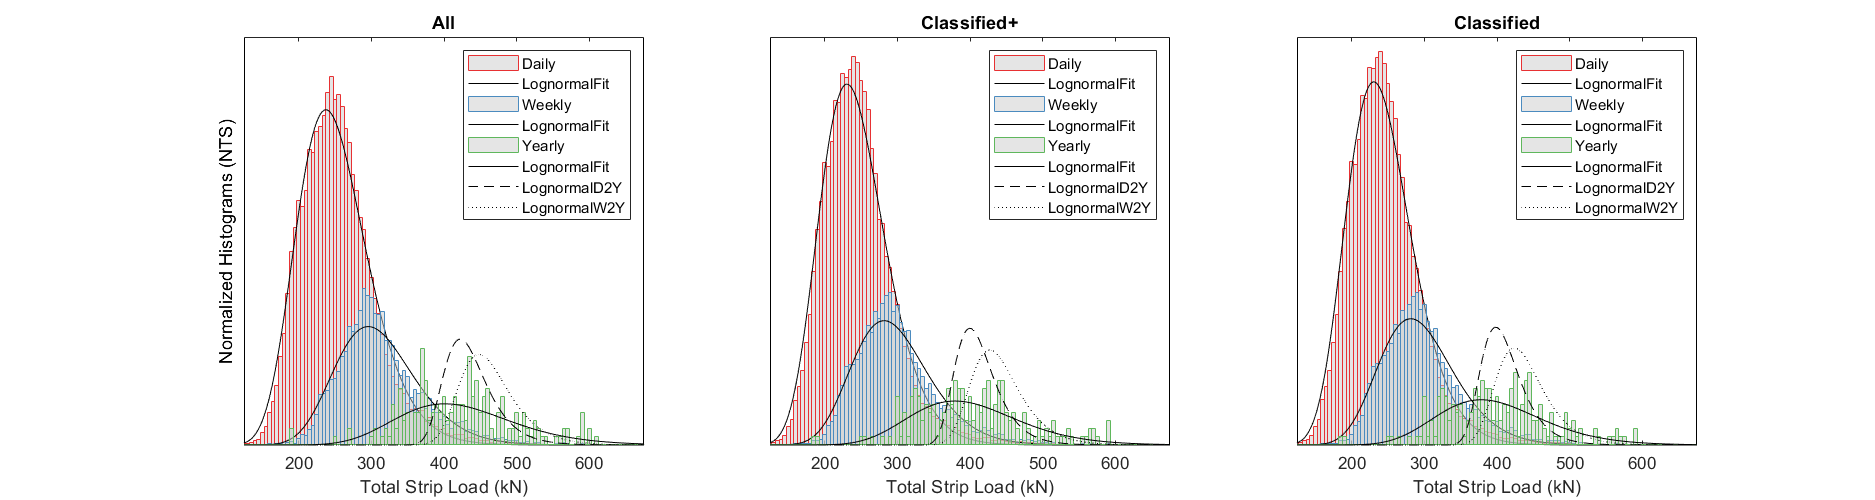

% Initial commands
clear, clc, close all
% Inputs
BM = {'Daily', 'Weekly', 'Yearly'};             % j
ClassType = {'All', 'ClassOW', 'Class'};        % i
ClassT = {'All', 'Classified+', 'Classified'};
DistTypes = {'Normal', 'Lognormal', 'GeneralizedExtremeValue'};
load('Q1Q2MaxEventsxMax.mat')
load('Q1Q2MaxEventsxpd.mat')
load('Q1Q2MaxEventsxy_values.mat')
x_values = 0:1:1000; % Must match those used to create y_values in Step 4

figure('Position',[0 0 1500 400]);

% Set colours
C = linspecer(9);
% ScaleDown
ScaleDown = [1 2.5 5];
% X Stuff
Step = 5;
LimitL = 100;
LimitR = 700;
X = LimitL:Step:LimitR;
x = X(1:end-1) + diff(X);
    
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    subplot(1,3,i)
    hold on
    
    for j = 1:length(BM)
        BlockM = BM{j};
        
        y = histcounts(Max.(Class).(BlockM).Max,'BinEdges',X,'normalization','pdf');
        bar(x,y/ScaleDown(j),1,'EdgeColor',C(j,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.5,'DisplayName',BlockM)
        
        for k = 2
            Dist = DistTypes{k};
       
            plot(x_values,y_values.(Class).(BlockM).(Dist).PDF_Fit/ScaleDown(j),'k-','DisplayName',[Dist 'Fit'])
            
            if strcmp(BlockM,'Yearly')
                
                plot(x_values,y_values.(Class).(BlockM).(Dist).PDF_D2Y/ScaleDown(j),'k--','DisplayName',[Dist 'D2Y'])
                plot(x_values,y_values.(Class).(BlockM).(Dist).PDF_W2Y/ScaleDown(j),'k:','DisplayName',[Dist 'W2Y'])
            end
            
        end
    end
    
    % Set Plot Details
    set(gca,'ytick',[],'yticklabel',[],'ycolor','k')
    box on
    xlim([LimitL+25 LimitR-25])
    if i == 1
        ylabel('Normalized Histograms (NTS)')
    end
    xlabel('Total Strip Load (kN)')
    title([ClassT{i}])
    legend('location','northeast')
    
end

#### *Block Maxima Compared between each other*

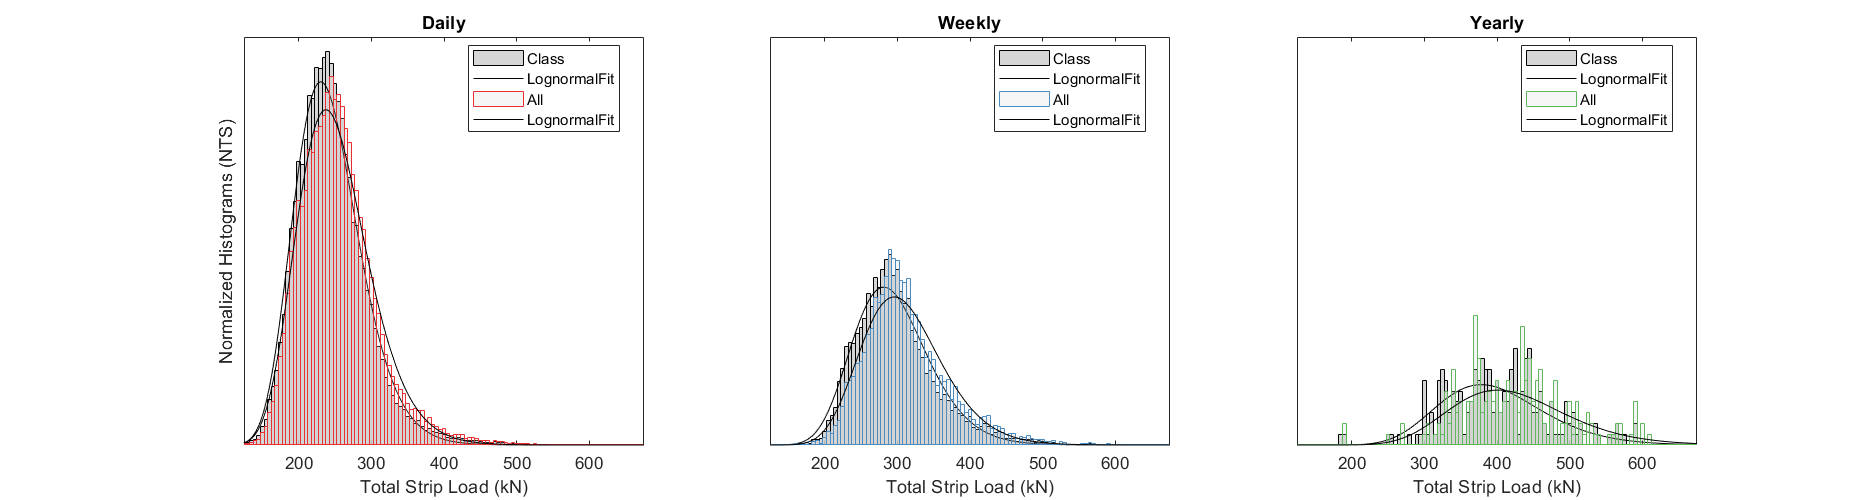

figure('Position',[0 0 1500 400]);

% X Stuff
Step = 2.5;
LimitL = 100; LimitR = 700;
Xp = LimitL-Step/2:Step:LimitR-Step/2;

for j = 1:length(BM)
    BlockM = BM{j};
    
    subplot(1,3,j)
    hold on
    k = 2;
    
    Class = 'Class';
    y = histcounts(Max.(Class).(BlockM).Max,'BinEdges',X,'normalization','pdf');
    bar(x,y/ScaleDown(j),1,'EdgeColor','k','FaceColor',[.8 .8 .8],'FaceAlpha',0.8,'DisplayName',Class)
    
    Dist = DistTypes{k};
    plot(x_values,y_values.(Class).(BlockM).(Dist).PDF_Fit/ScaleDown(j),'k-','DisplayName',[Dist 'Fit'])    
    
    Class = 'All';
    y = histcounts(Max.(Class).(BlockM).Max,'BinEdges',X,'normalization','pdf');
    bar(x,y/ScaleDown(j),1,'EdgeColor',C(j,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.2,'DisplayName',Class)
    
    Dist = DistTypes{k};
    plot(x_values,y_values.(Class).(BlockM).(Dist).PDF_Fit/ScaleDown(j),'k-','DisplayName',[Dist 'Fit'])
    
    % Set Plot Details
    a = ylim;
    ylim([a(1) a(2)*j])
    box on
    set(gca,'ytick',[],'yticklabel',[])
    if j == 1
        ylabel('Normalized Histograms (NTS)')
    end
    xlabel('Total Strip Load (kN)')
    title(BlockM)
    legend('location','best')
    xlim([LimitL+25 LimitR-25])
    
end

#### *Block Maxima Compared for Classification Filters*

### Step 6: Probability Paper Plotting & Tail Fitting Methods

When we apply the above equations, we are assuming the maximums are normally or log-normally distributed. We should evaluate the fit with a probability paper plot.

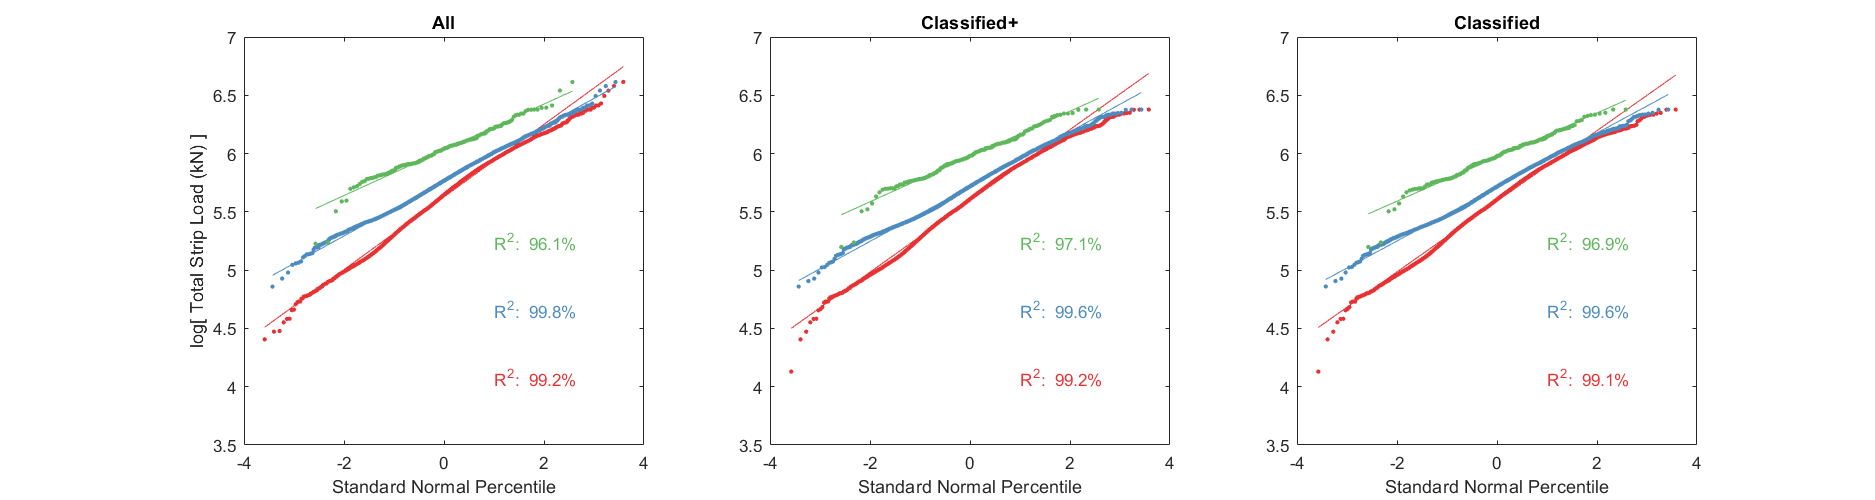

figure('Position',[0 0 1500 400]);
   
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    for j = 1:length(BM)
        BlockM = BM{j};
        subplot(1,3,i)
        hold on
        
        [MaxECDF, MaxECDFRank] = ecdf(Max.(Class).(BlockM).Max); MaxECDFRank = MaxECDFRank'; MaxECDF(1) = []; MaxECDFRank(1) = [];
        
        scatter(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),log(MaxECDFRank),7,C(j,:),'filled','DisplayName','Max Data');
        mdl = fitlm(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),log(MaxECDFRank),'linear');
        
        x2 = norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1));
        y2 = log(MaxECDFRank);
        
        md2 = fitlm(x2(round(length(x2)*3/4):length(x2)),y2(round(length(x2)*3/4):length(x2)),'linear');
        
        plot(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),mdl.Fitted,'-','Color',C(j,:),'DisplayName',['Fitted ' num2str(mdl.Rsquared.Ordinary,3)]);
        %plot(x2(round(length(x2)*3/4):length(x2)),md2.Fitted,'-','Color','k','DisplayName',['Fitted ' num2str(md2.Rsquared.Ordinary,3)]);
        
        
        %text(1,y1(1)+(y1(2)-y1(1))/j,['\lambda = ' sprintf('%.2f \n',mdl.Coefficients.Estimate(1)) '\zeta = ' sprintf('%.2f \n',mdl.Coefficients.Estimate(2)) sprintf('R^2:  %.1f%%',mdl.Rsquared.Ordinary*100)])

        box on
        xlim([-4 4])
        ylim([3.5 7])
        y1 = ylim;
        text(1,y1(1)+(y1(2)-y1(1))*(j/6),sprintf('R^2:  %.1f%%',mdl.Rsquared.Ordinary*100),"Color",C(j,:))
        Fit(i,j) = mdl.Rsquared.Ordinary*100;
        
    end
    
    if i == 1
        ylabel('log[ Total Strip Load (kN) ]')
    end
    xlabel('Standard Normal Percentile')
    %legend('Location', 'southeast')
    title([ClassT{i}])
    
end

#### *LogNormal Probability Paper*

### Step 7: Summarize $\alpha_Q$ Estimates

*We account for the fact that the reliability index, *$\beta$, *must be for the same reference period as *$E_{m,\textrm{act}}$

Normal Distribution:                            $E_{d,\textrm{act}} =E_{m,\textrm{act}} \cdot \left\lbrack 1+\alpha \beta \nu \right\rbrack$

Lognormal Distribution:                      $E_{d,\textrm{act}} =E_{m,\textrm{act}} \cdot \exp \left\lbrack \alpha \beta \delta -0\ldotp 5\delta^2 \right\rbrack$      where         $\delta^2 =\ln \left(\nu^2 +1\right)$

% According to Annex C of SIA 269
Beta.Yearly = 4.7; % Here we use the Beta annual - so we should use annual max effects
Beta.Weekly = 5.44422; % See Tail Fitting > Beta Conversion
Beta.Daily = 5.72397;
% Importance Coefficient
Alpha = 0.7;
AQ1 = 0.60;

SumTableLogNorm = array2table(zeros(8,length(BM)*length(ClassType)));
SumTableLogNorm.Properties.VariableNames = {[BM{3} ' ' ClassType{1}], [BM{3} ' ' ClassType{2}], [BM{3} ' ' ClassType{3}], [BM{2} ' ' ClassType{1}],...
    [BM{2} ' ' ClassType{2}], [BM{2} ' ' ClassType{3}], [BM{1} ' ' ClassType{1}], [BM{1} ' ' ClassType{2}], [BM{1} ' ' ClassType{3}]};
SumTableLogNorm.Properties.RowNames = {'Em', 'Ed', 'Ed (%ile*10)', 'LNFit (%)', 'AlphaQN', 'AlphaQLN', 'AlphaQ2N', 'AlphaQ2LN'};

SumTableLogNormComp = array2table(zeros(2,(length(BM)-1)*length(ClassType)));
SumTableLogNormComp.Properties.RowNames = {'AlphaQLN', 'AlphaQ2LN'};
SumTableLogNormComp.Properties.VariableNames = {['W2Y ' ClassType{1}],['W2Y ' ClassType{2}],['W2Y ' ClassType{3}],['D2Y ' ClassType{1}],['D2Y ' ClassType{2}],['D2Y ' ClassType{3}]};

for i = 1:length(ClassType)
    Class = ClassType{i};

    for j = 1:length(BM)
        BlockM = BM{j};
            
        Em = mean(Max.(Class).(BlockM).Max);
        Stdev = std(Max.(Class).(BlockM).Max);
        COV = Stdev/Em;
        Delta2 = log(COV^2+1);   
        Dist95N = norminv(0.95,pd.(Class).(BlockM).Normal.mu,pd.(Class).(BlockM).Normal.sigma);
        Dist95LN = logninv(0.95,pd.(Class).(BlockM).Lognormal.mu,pd.(Class).(BlockM).Lognormal.sigma);
        
        EdN = Em*(1+Alpha*Beta.(BlockM)*COV);
        AQN = EdN/(1.5*1000);
        AQ2N = (EdN/(1.5)-AQ1*600)/400;
        EdLN = Em*exp(Alpha*Beta.(BlockM)*sqrt(Delta2)-0.5*Delta2);
        AQLN = EdLN/(1.5*1000);
        AQ2LN = (EdLN/(1.5)-AQ1*600)/400;
        
        % Find %ile corresponding to Ed
        N5 = prctile(Max.(Class).(BlockM).Max,95);
        I95 = invprctile(Max.(Class).(BlockM).Max,EdLN);

        SumTableLogNorm.([BlockM ' ' Class]) = [Em; EdLN; I95*10; Fit(i,j); AQN; AQLN; AQ2N; AQ2LN];
        
        if strcmp(BlockM,'Weekly')
            pdx = pd.(Class).W2Y.Lognormal;
            Delta2 = pdx.sigma^2;
            Em = exp(pdx.mu+0.5*Delta2);
            SumTableLogNormComp.(['W2Y ' Class]) = [Em*exp(Alpha*Beta.Yearly*sqrt(Delta2)-0.5*Delta2)/(1.5*1000); (Em*exp(Alpha*Beta.Yearly*sqrt(Delta2)-0.5*Delta2)/(1.5)-AQ1*600)/400];
        elseif strcmp(BlockM,'Daily')
            pdx = pd.(Class).D2Y.Lognormal;
            Delta2 = pdx.sigma^2;
            Em = exp(pdx.mu+0.5*Delta2);
            SumTableLogNormComp.(['D2Y ' Class]) = [Em*exp(Alpha*Beta.Yearly*sqrt(Delta2)-0.5*Delta2)/(1.5*1000); (Em*exp(Alpha*Beta.Yearly*sqrt(Delta2)-0.5*Delta2)/(1.5)-AQ1*600)/400];
        end
    end
end

format bank
disp(SumTableLogNorm)

                    Yearly All    Yearly ClassOW    Yearly Class    Weekly All    Weekly ClassOW    Weekly Class    Daily All    Daily ClassOW    Daily Class
                    __________    ______________    ____________    __________    ______________    ____________    _________    _____________    ___________

    Em                423.92          400.68           398.45         311.12          296.50           295.59        252.43         244.00          243.59   
    Ed                774.13          723.37           706.77         630.13          598.98           589.67        565.87         529.17          525.54   
    Ed (%ile*10)

disp(SumTableLogNormComp)

                 W2Y All    W2Y ClassOW    W2Y Class    D2Y All    D2Y ClassOW    D2Y Class
                 _______    ___________    _________    _______    ___________    _________

    AlphaQLN      0.41         0.39          0.39        0.38          0.35          0.35  
    AlphaQ2LN     0.12         0.08          0.06        0.05         -0.02         -0.02  



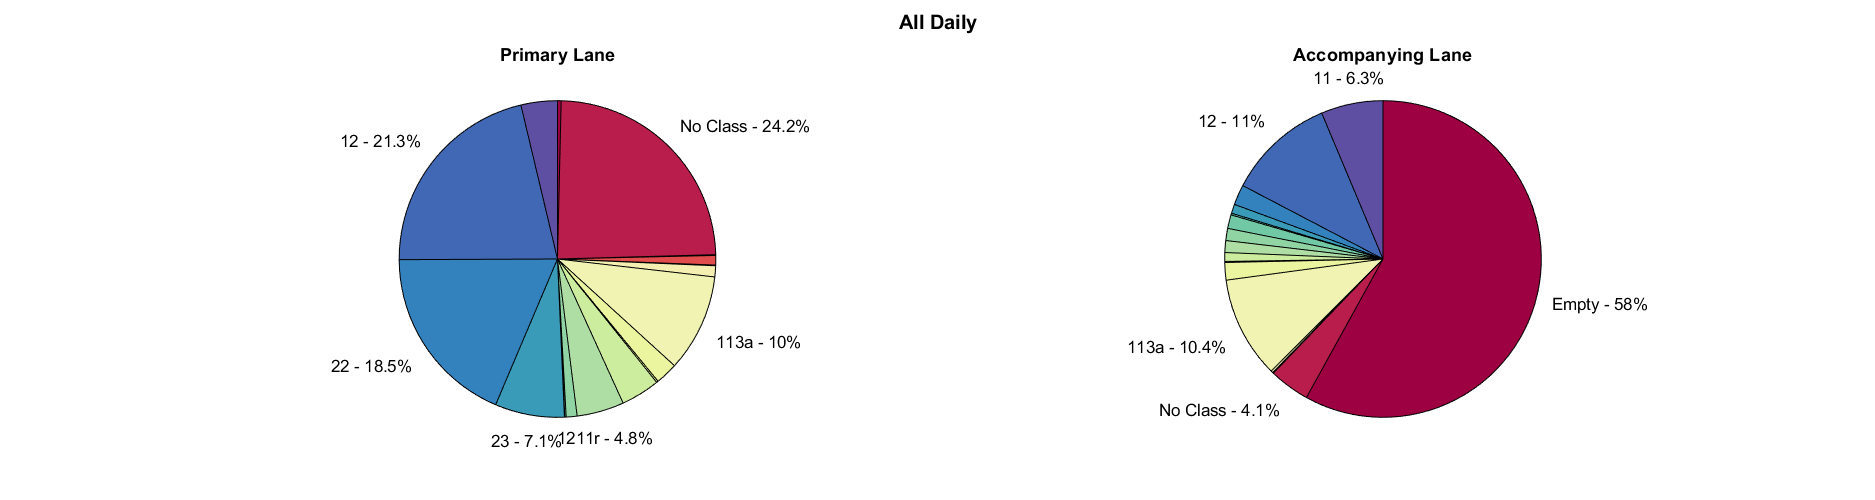

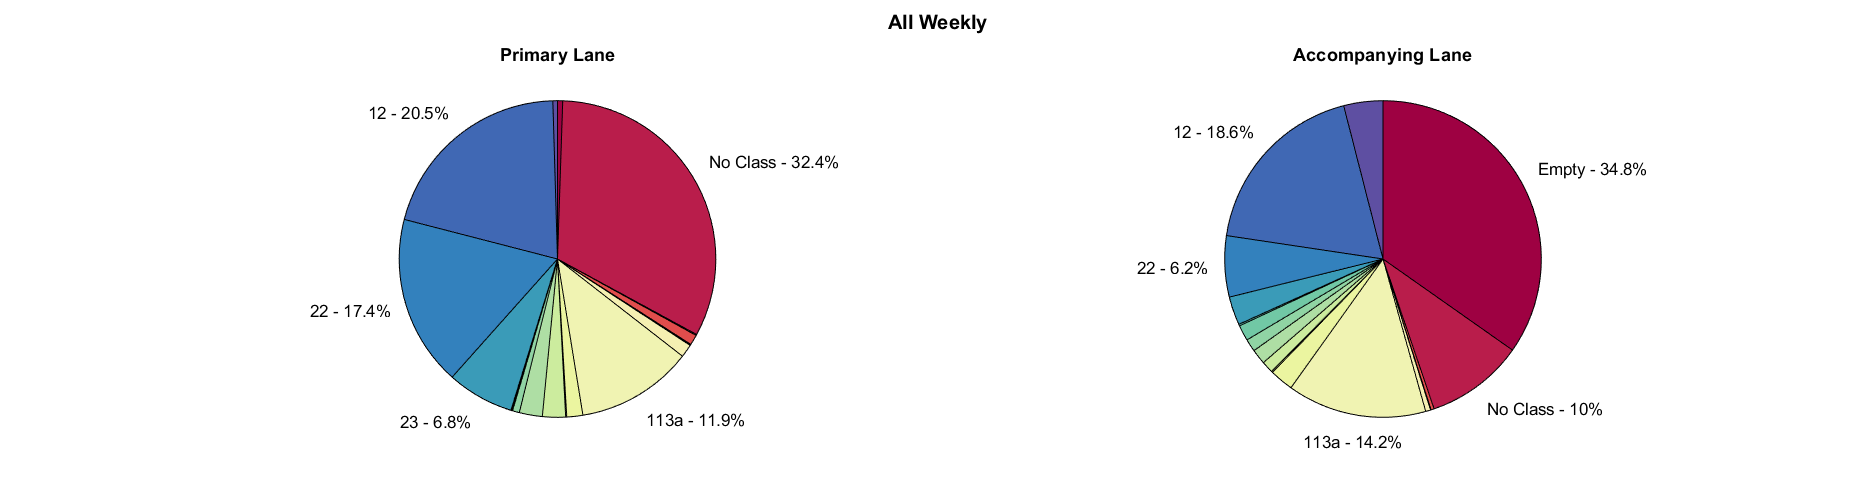

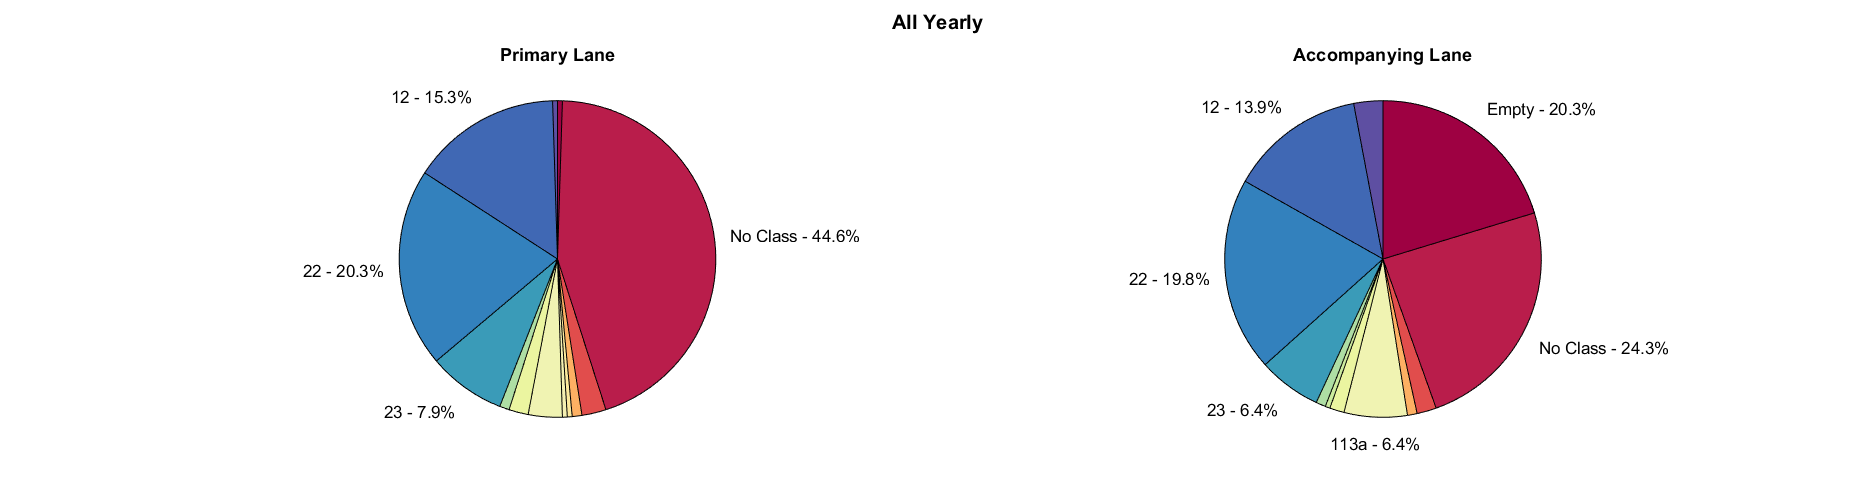

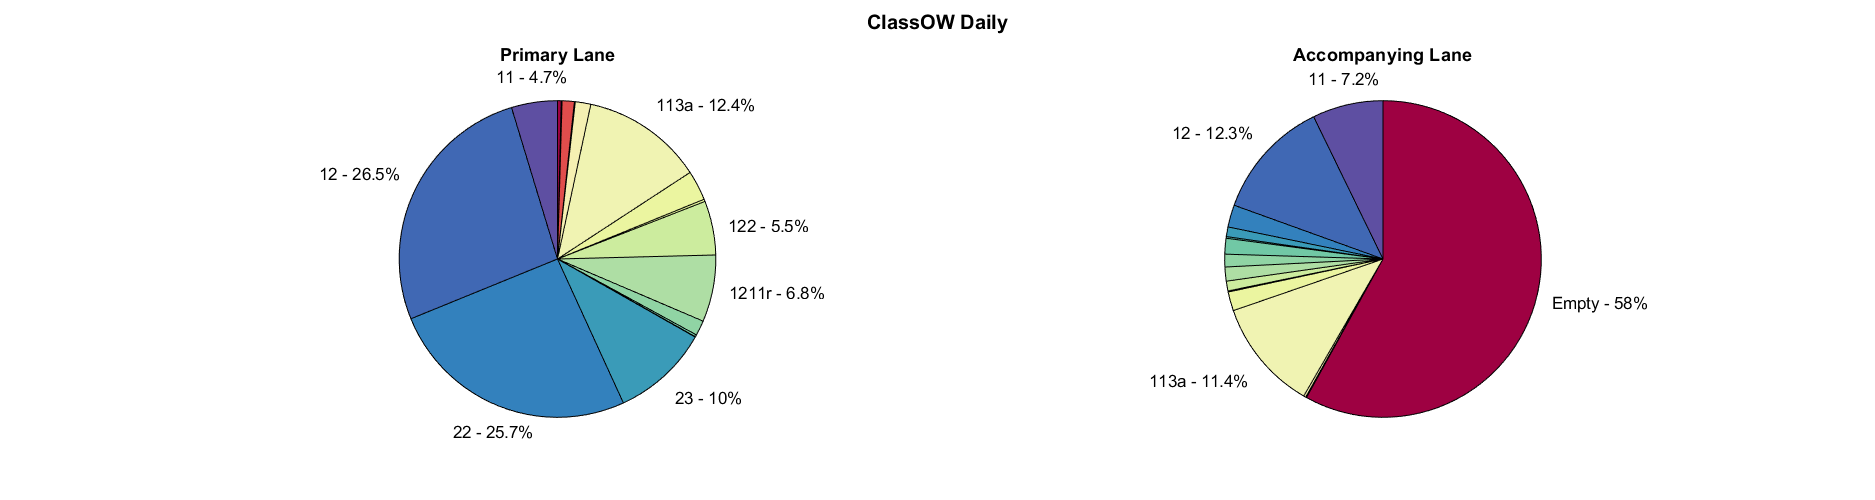

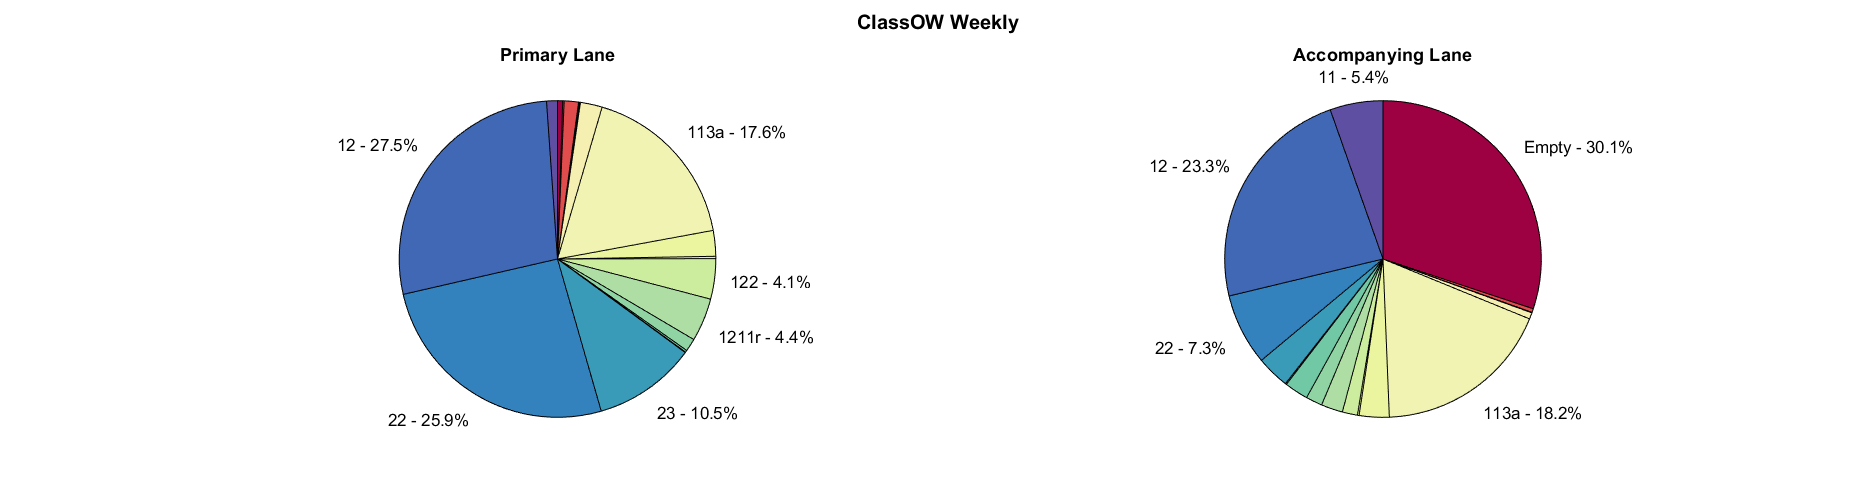

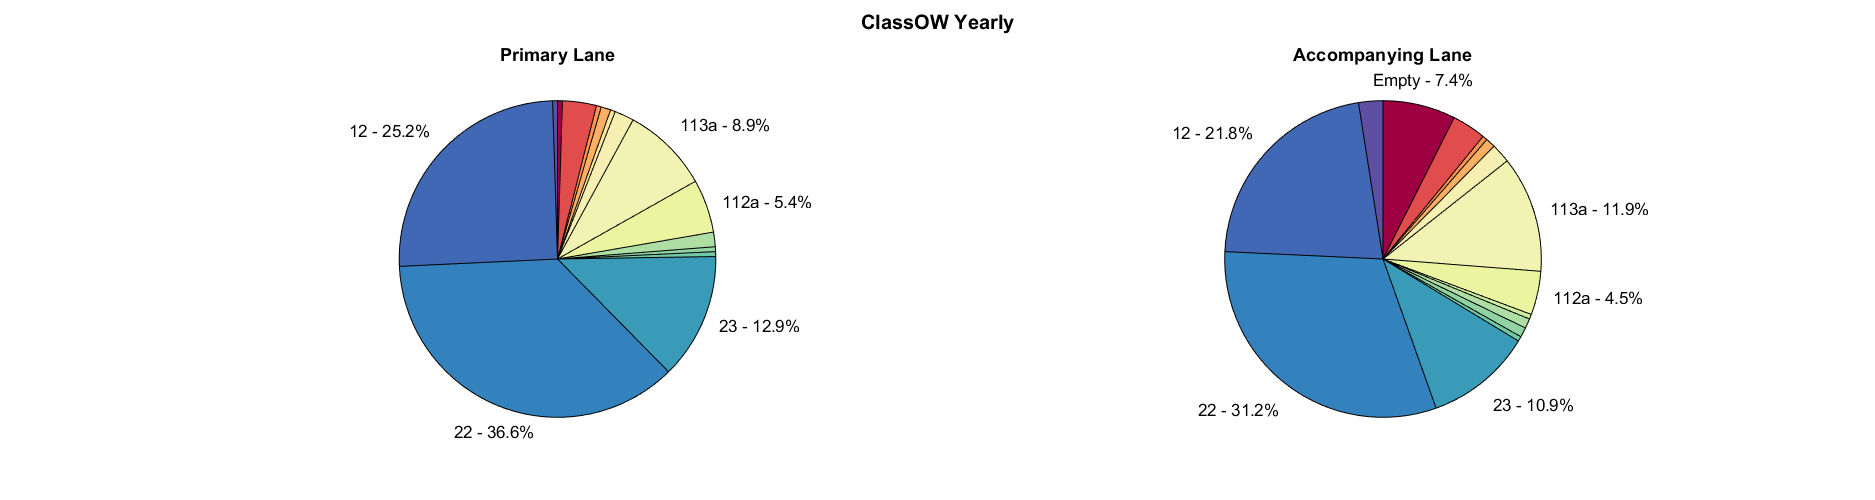

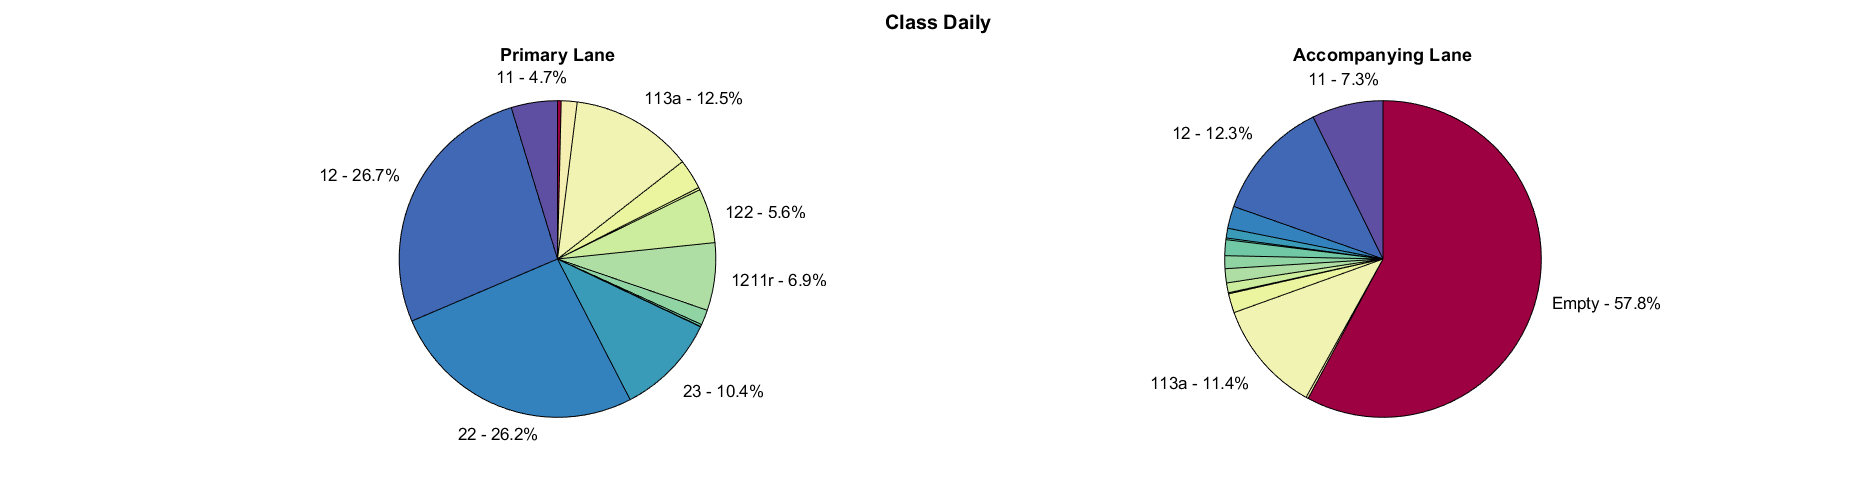

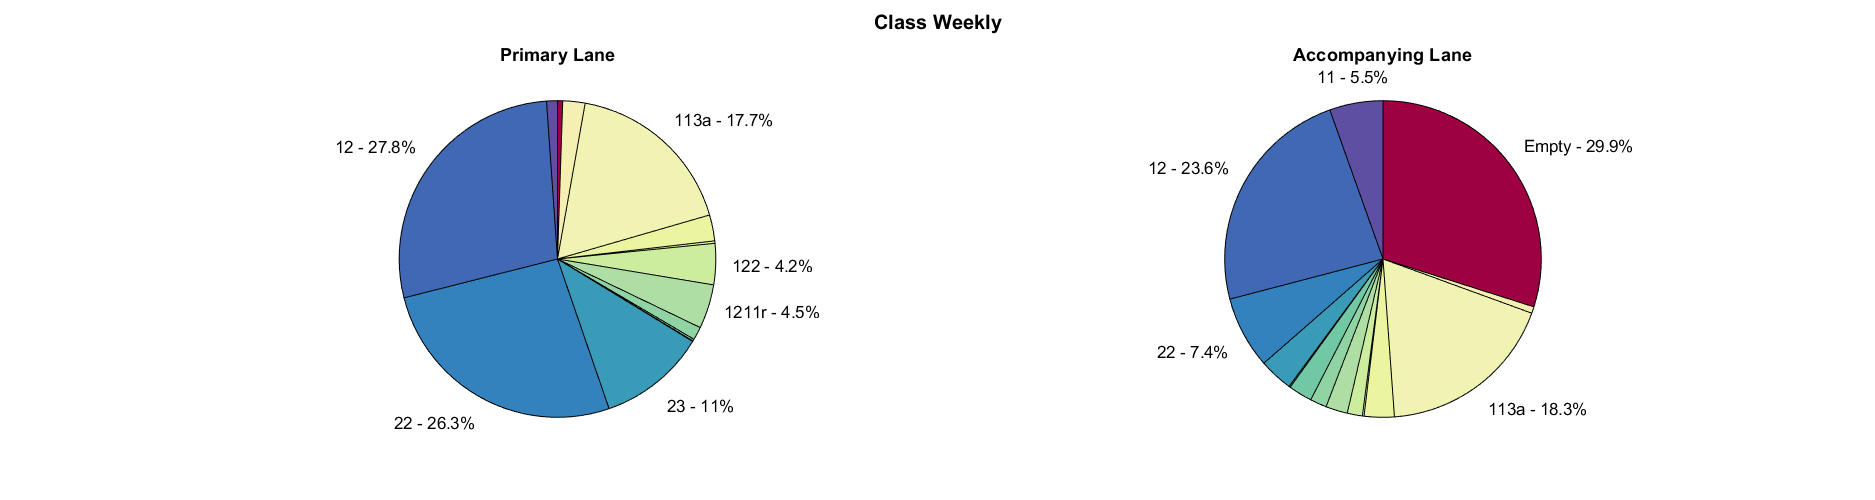

% What vehicles were involved?
TrTyps = [11; 12; 22; 23; 111; 11117; 1127; 12117; 122; 11127; 1128; 1138; 1238; 41; 42; 43; 44; 45; 46; 47; 48; 49; 0; 99];
TN = ["11" "12" "22" "23" "111" "1111r" "112r" "1211r" "122" "11112r" "112a" "113a" "123a"...
    "60t Crane" "6ax 60t" "7ax 72t" "8ax 84t" "9ax 96t" "96t Crane" "Libherr 132" "Libherr 15" "84t AT7" "No Class" "Empty"]';

% For each ClassType (or in this case just All and Class)
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    % Select Daily, Weekly, or Yearly
    for j = 1:length(BM)
        BlockM = BM{j};
        
        figure('Position',[0 0 1500 400]);
        hold on
        
        % Get Primary Lane and Accompanying Lane Vehicles
        Primary = zeros(height(Max.(Class).(BlockM)),1); Accomp = Primary;
        [~, Ind] = max([Max.(Class).(BlockM).L1Load'; Max.(Class).(BlockM).L2Load']); Ind = Ind';
        Primary(Ind == 1) = Max.(Class).(BlockM).L1Veh(Ind == 1); Primary(Ind == 2) = Max.(Class).(BlockM).L2Veh(Ind == 2);
        Accomp(Ind == 1) = Max.(Class).(BlockM).L2Veh(Ind == 1); Accomp(Ind == 2) = Max.(Class).(BlockM).L1Veh(Ind == 2);
        
        PrimaryC = categorical(Primary); AccompC = categorical(Accomp);
        [N, Cats] = histcounts(PrimaryC,categorical(TrTyps)); [Nx] = histcounts(AccompC,categorical(TrTyps));
        
        Label = cell(length(TN),1); Labelx = cell(length(TN),1);
        Perc = 100*N/sum(N); Percx = 100*Nx/sum(Nx);
        PercS = string(round(Perc,1))'; PercSx = string(round(Percx,1))';
        
        for p = 1:length(TN)
            if Perc(p) > 4
                Label{p} = [TN{p} ' - ' PercS{p} '%'];  else;  Label{p} = '';
            end
            if Percx(p) > 4
                Labelx{p} = [TN{p} ' - ' PercSx{p} '%'];  else;  Labelx{p} = '';
            end
        end
        
        % We need colors to be the same for each TrTyp
        % Labels should be strings that include the percentages
        
        subplot(1,2,1)
        sgtitle([Class ' ' BlockM],'fontweight','bold','fontsize',12);
        h = pie(N,Label);
        newColors = linspecer(numel(N));
        % Isolate the patch handles
        patchHand = findobj(h, 'Type', 'Patch');
        % Set the color of all patches using the nx3 newColors matrix
        set(patchHand, {'FaceColor'}, mat2cell(newColors, ones(size(newColors,1),1), 3))
        title('Primary Lane')
        subplot(1,2,2)
        h = pie(Nx,Labelx);
        % Isolate the patch handles
        patchHand = findobj(h, 'Type', 'Patch');
        set(patchHand, {'FaceColor'}, mat2cell(newColors, ones(size(newColors,1),1), 3))
        title('Accompanying Lane')
        
        if strcmp(Class,'ClassOW') && strcmp(BlockM,'Daily')
            NAD = N + Nx; NADnorm = NAD/sum(NAD);
        elseif  strcmp(Class,'ClassOW') && strcmp(BlockM,'Yearly')
            NAY = N + Nx; NAYnorm = NAY/sum(NAY);
        elseif strcmp(Class,'ClassOW') && strcmp(BlockM,'Weekly')
            NAW = N + Nx; NAWnorm = NAW/sum(NAW);
        end
    end
end

#### *Classification of Vehicles Involved*

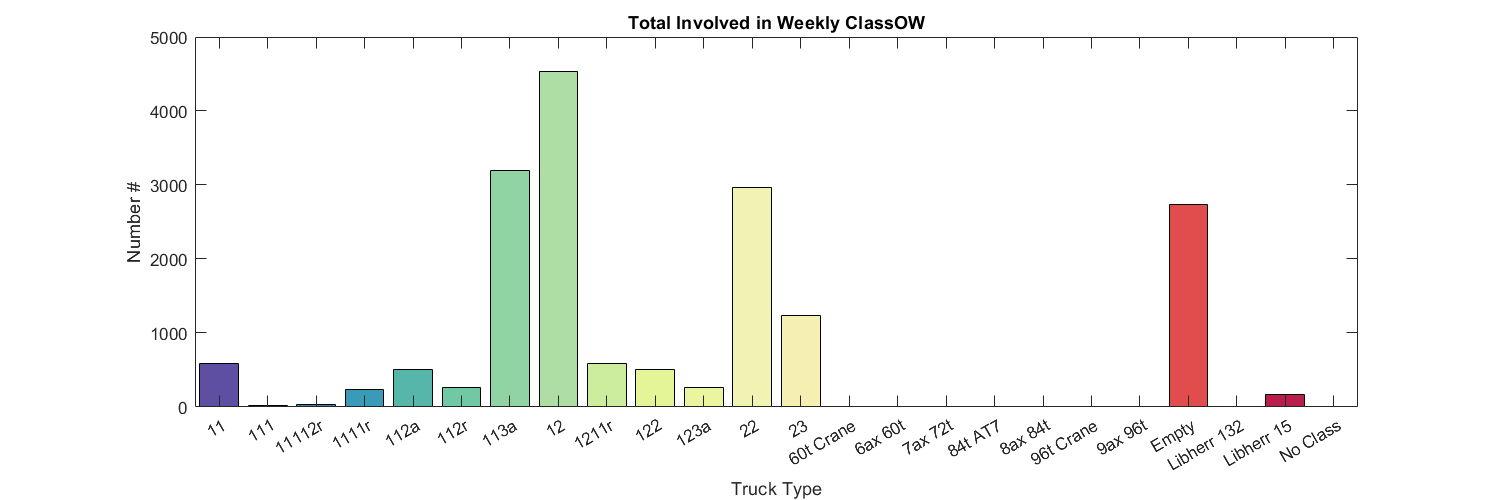

% Lets do the comparison between AllDaily and AllYearly
figure('Position',[0 0 1200 400]);
b = bar(categorical(TN),NAW);
b.FaceColor = 'flat';
b.CData(:,:) = newColors;
ylabel('Number #')
xlabel('Truck Type')
title('Total Involved in Weekly ClassOW')

#### Presence of HV (Class OW, Yearly)

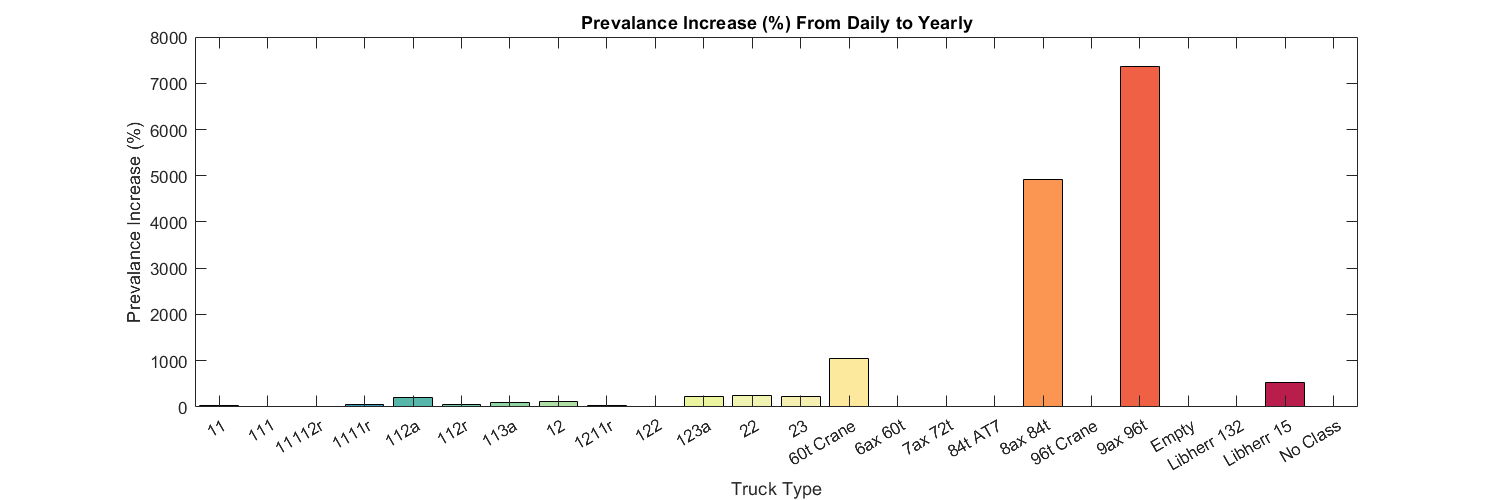

figure('Position',[0 0 1200 400]);
b = bar(categorical(TN),100*NAYnorm./NADnorm);
b.FaceColor = 'flat';
b.CData(:,:) = newColors;
ylabel('Prevalance Increase (%)')
xlabel('Truck Type')
title('Prevalance Increase (%) From Daily to Yearly')

#### Prevalance Increase

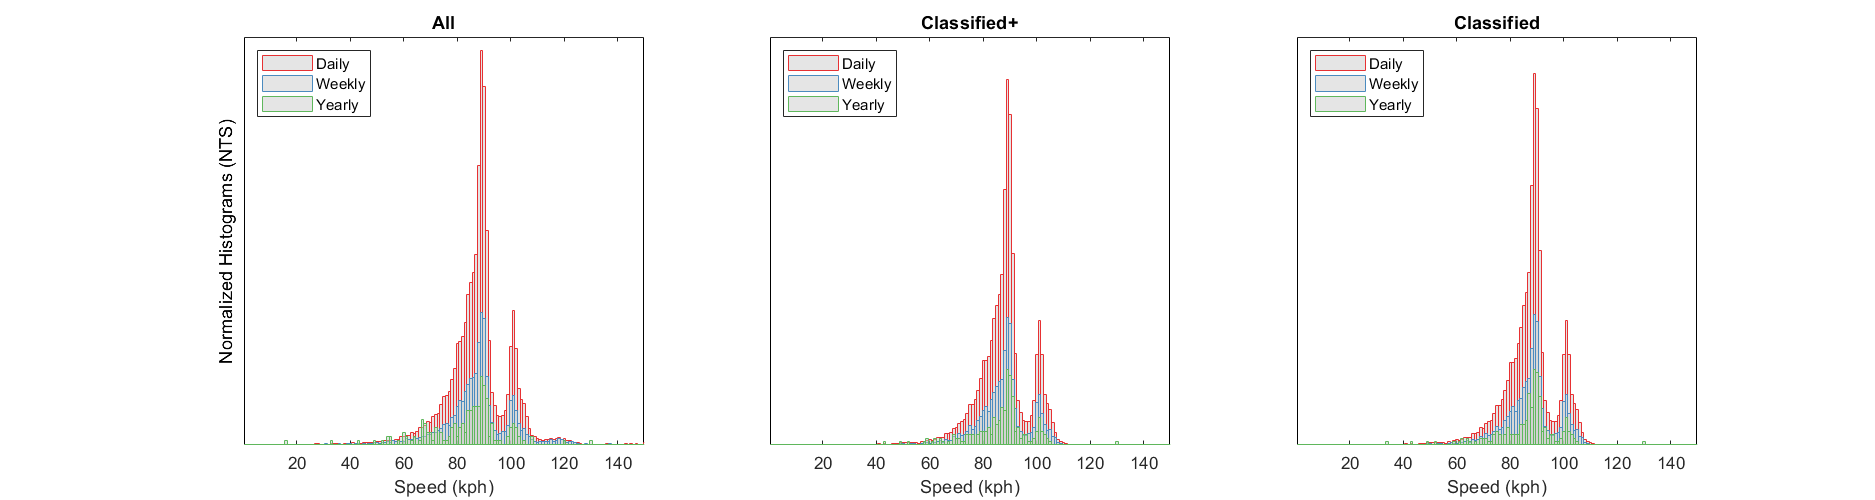


% I should add SPEED
figure('Position',[0 0 1500 400]);

% X Stuff
Step = 1;
LimitL = 0;
LimitR = 150;
X = LimitL:Step:LimitR;
%Xp = LimitL-Step/2:Step:LimitR-Step/2;
x = X(1:end-1) + diff(X);

for i = 1:length(ClassType)
    Class = ClassType{i};
    
    subplot(1,3,i)
    hold on
    
    for j = 1:length(BM)
        BlockM = BM{j};
        
        y = histcounts(Max.(Class).(BlockM).L1Sp(Max.(Class).(BlockM).L1Sp>0),'BinEdges',X,'normalization','pdf');
        bar(x,y/ScaleDown(j),1,'EdgeColor',C(j,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.5,'DisplayName',BlockM)
        
    end
    
    % Set Plot Details
    set(gca,'ytick',[],'yticklabel',[],'ycolor','k')
    box on
    xlim([LimitL+.25 LimitR-.25])
    if i == 1
        ylabel('Normalized Histograms (NTS)')
    end
    xlabel('Speed (kph)')
    title([ClassT{i}])   
    legend('location','northwest')
    
end

#### Speed of Vehicles Involved

#### Function(s)

function out = maxIndex(Z)
    [ymax, loc]=max(sum([Z(:,6) Z(:,7)],2));
    out=[ymax, Z(loc,:)];
end